clear all;

## Constant length lever

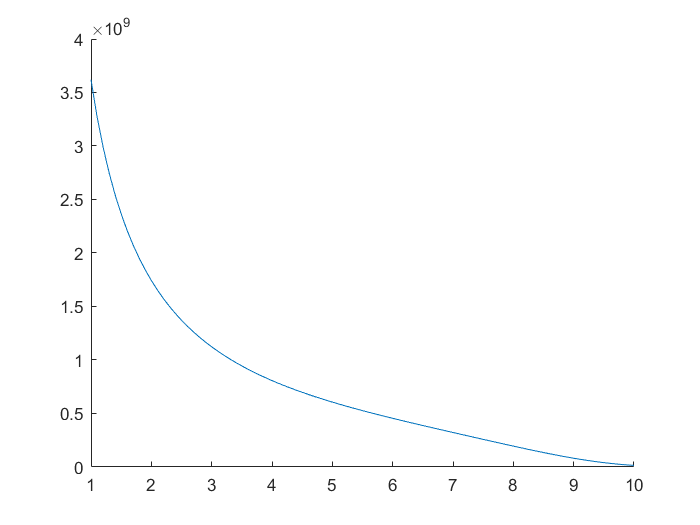

Ea = 13.4E10; %elastic modulus ceramic
Em = 210E9; %elastic modulus steel

MA = transpose([1:0.1:10]); %mechanical advantage B/A (for whole integer numbers)
L1 = length(MA);

%Prealocating space for matrices
A = zeros(1,L1); B = zeros(1,L1);
h_a = zeros(1,L1); %actuator height
h_l = zeros(1,L1); %lever height
Ca = zeros(1,L1); %stiffness actuator
C_tot = zeros(1,L1);
Ua = zeros(1,L1); Ul = zeros(1,L1);

S_out = 10; %micrometers
S0 = 3.3; %micrometers
h0 = 2E-3; %m

w_a = 15E-3; %width of the actuator

leverThic = 40E-3; %m

totalHeight = 90E-3; %m
LeverLength = 100E-3; %m
for i=1:L1
    Ma = 1 / MA(i); %Mechanical advantage A/B (easier for computations)
    A(i) = LeverLength*Ma/(1+Ma); 
    B(i) = LeverLength/(1+Ma);
    h_a(i) = (1/Ma) * (S_out/S0 + 1) * h0;
    h_l(i) = totalHeight - h_a(i);
   
    Ca(i) = Ea * w_a^2 / h_a(i);
    I = h_l(i)^3 * leverThic;
    Ua(i) = 0.5/Ca(i);
    Ul(i) =  ( B(i)*A(i) )/((Ma^2)* 6 * LeverLength * Em * I ) * (LeverLength^2 - B(i)^2 - A(i)^2);
    C_tot(i) = 0.5 * (Ua(i) + Ul(i) )^-1;
end
figure()
clf;
hold on 

plot(MA,C_tot)

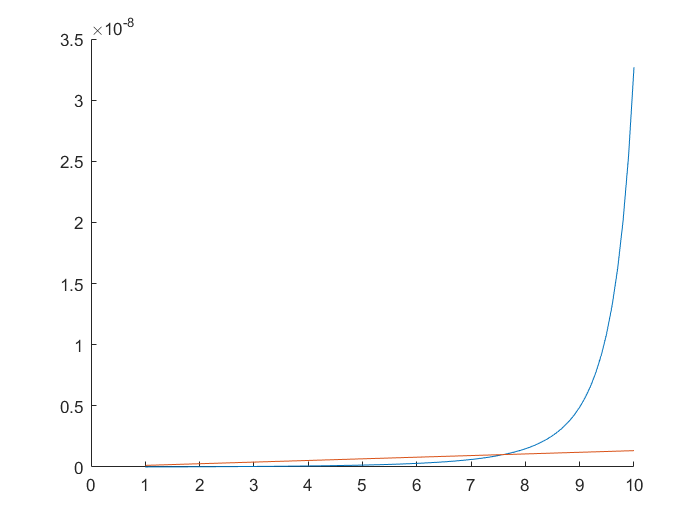

figure 
clf;
hold on
plot(MA,Ul)
plot(MA,Ua)
xlim([0 10])

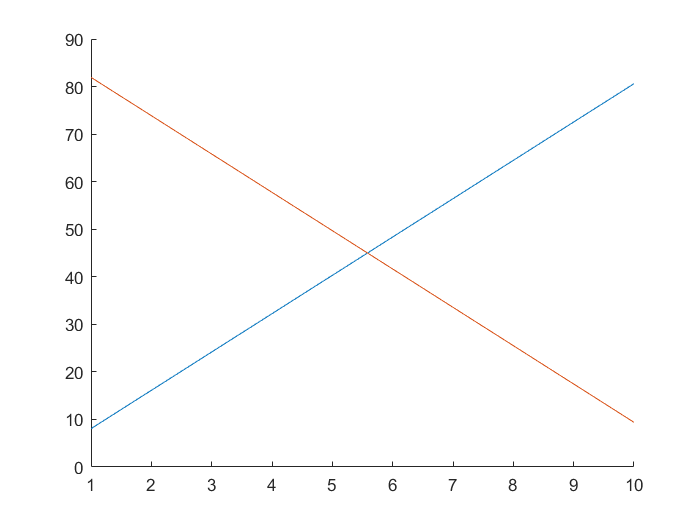






figure()
clf;
hold on
plot(MA,h_a*1E3)
plot(MA,h_l*1E3)
ylim([0 90])

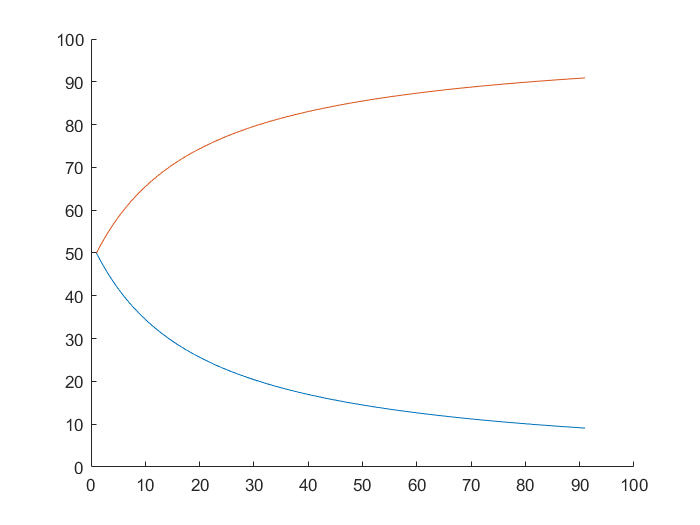


figure()
clf
hold on
plot(A*1E3)
plot(B*1E3)